## Load planC

planC = loadPlanC('C:\Users\s2ato\work\CERR\0001.mat', tempdir);

CERR>>  Loading 0001.mat...
CERR>>  Loaded 0001.mat...


planC = updatePlanFields(planC);
planC = quality_assure_planC('C:\Users\s2ato\work\CERR\Desktop_TestProstate.mat.bz2',planC);
indexS = planC{end}

indexS = struct with fields:
                header: 1
               comment: 2
                  scan: 3
            structures: 4
        structureArray: 5
    structureArrayMore: 6
                 beams: 7
          beamGeometry: 8
                  dose: 9
                   DVH: 10
                   IVH: 11
             planParam: 12
          seedGeometry: 13
           digitalFilm: 14
           RTTreatment: 15
                    IM: 16
                  GSPS: 17
                deform: 18
          registration: 19
               texture: 20
            featureSet: 21
             importLog: 22
          segmentLabel: 23
           CERROptions: 24
                indexS: 25


[CERR coordinate system](https://github.com/cerr/CERR/wiki/Coordinate-system)

Extract DVH

[i_ptv, structure] = getStructureFromName('Bladder', planC);
disp(structure.structureName);

Bladder


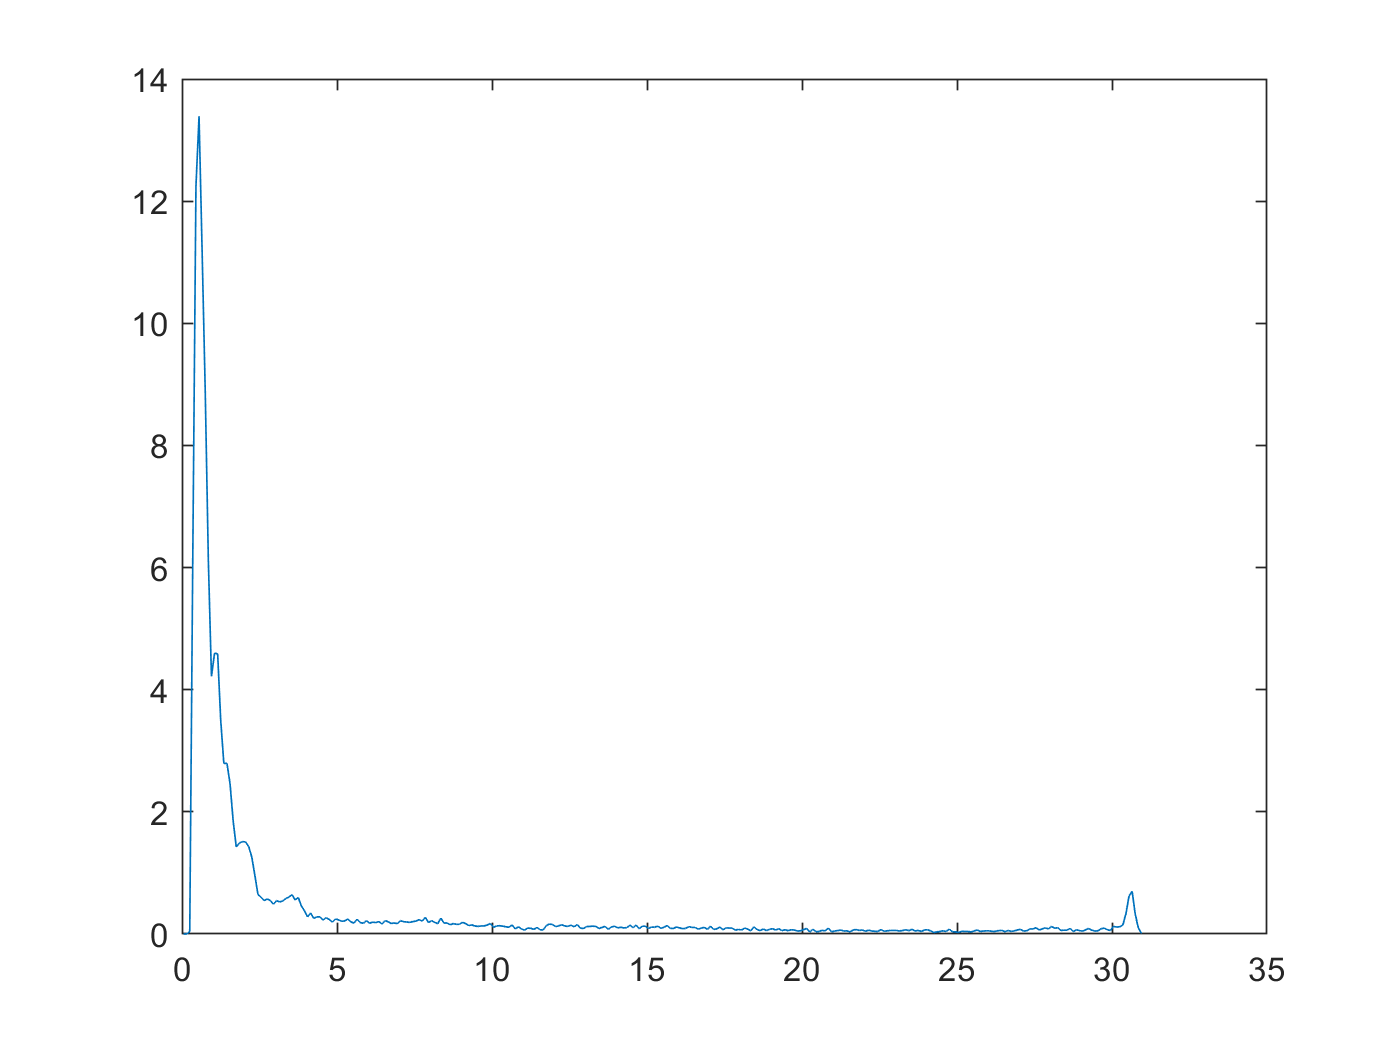

[i_plan, dose] = getPlanDoseFromId('1-1-2', planC);
[planC, doseBinsV, volsHistV] = getDVHMatrix(planC, i_ptv, i_plan);
plot(doseBinsV, volsHistV);

Cumulative DVH

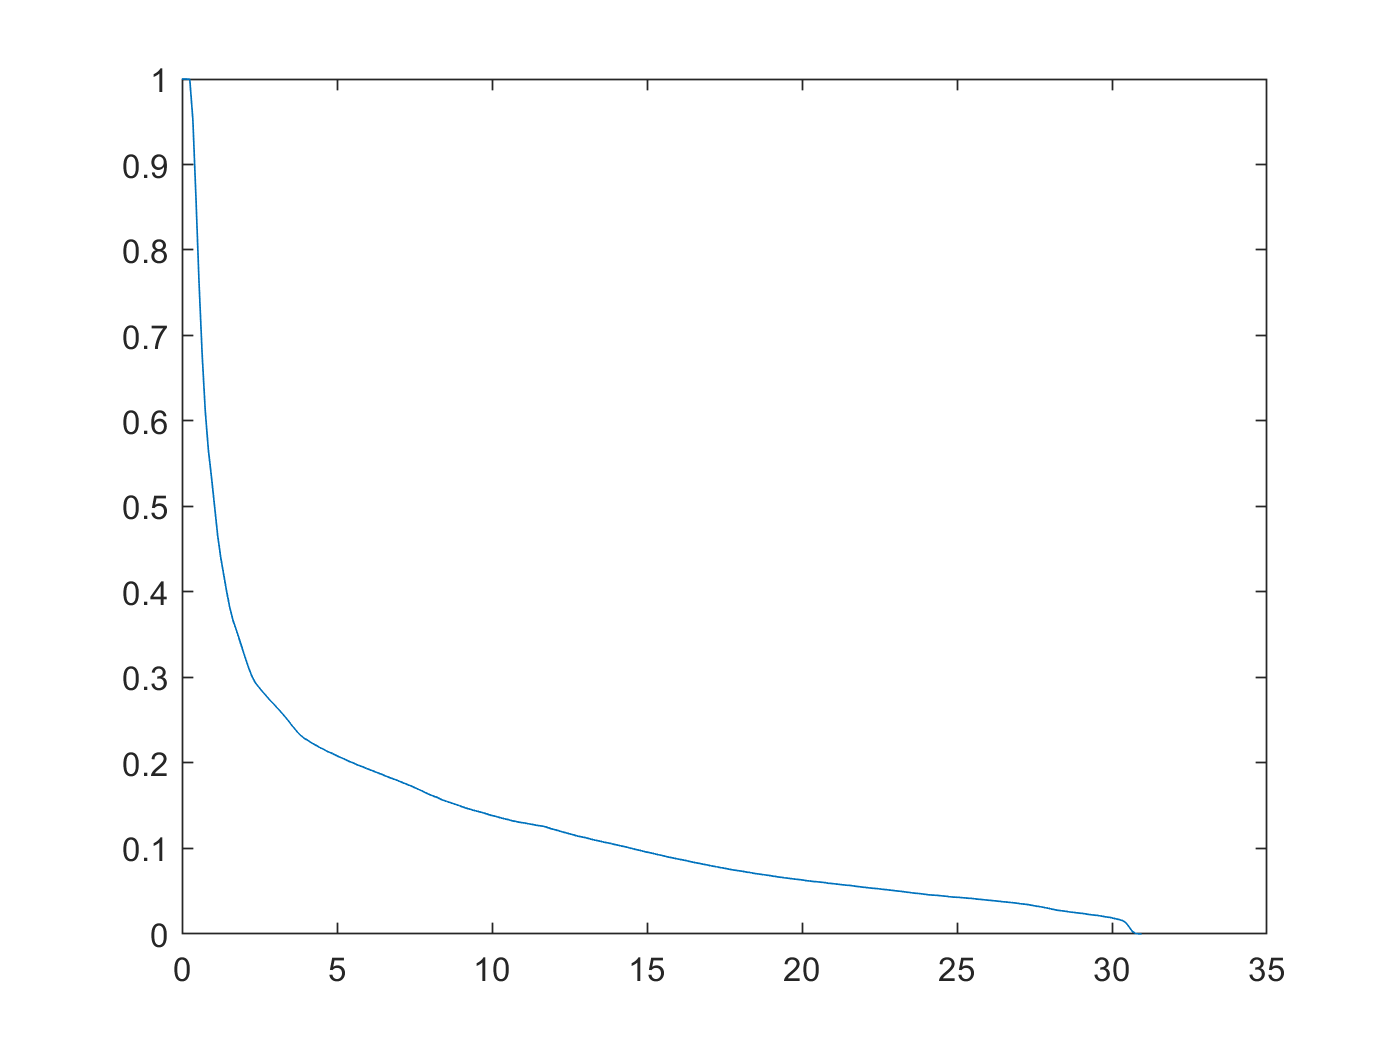

cumVolsV = cumsum(volsHistV);
cumVols2V  = cumVolsV(end) - cumVolsV;
% plot
figure,
plot([0, doseBinsV], [1, cumVols2V/cumVolsV(end)]);

PTV

[i_ptv, ptv] = getStructureFromName('PTV_Initial', planC);
disp(ptv.structureName);

PTV_Initial


[i_plan, dose] = getPlanDoseFromId('1-1-1', planC);
[planC, doseBinsV, volsHistV] = getDVHMatrix(planC, i_ptv, i_plan);
size(volsHistV)

ans =      1   481


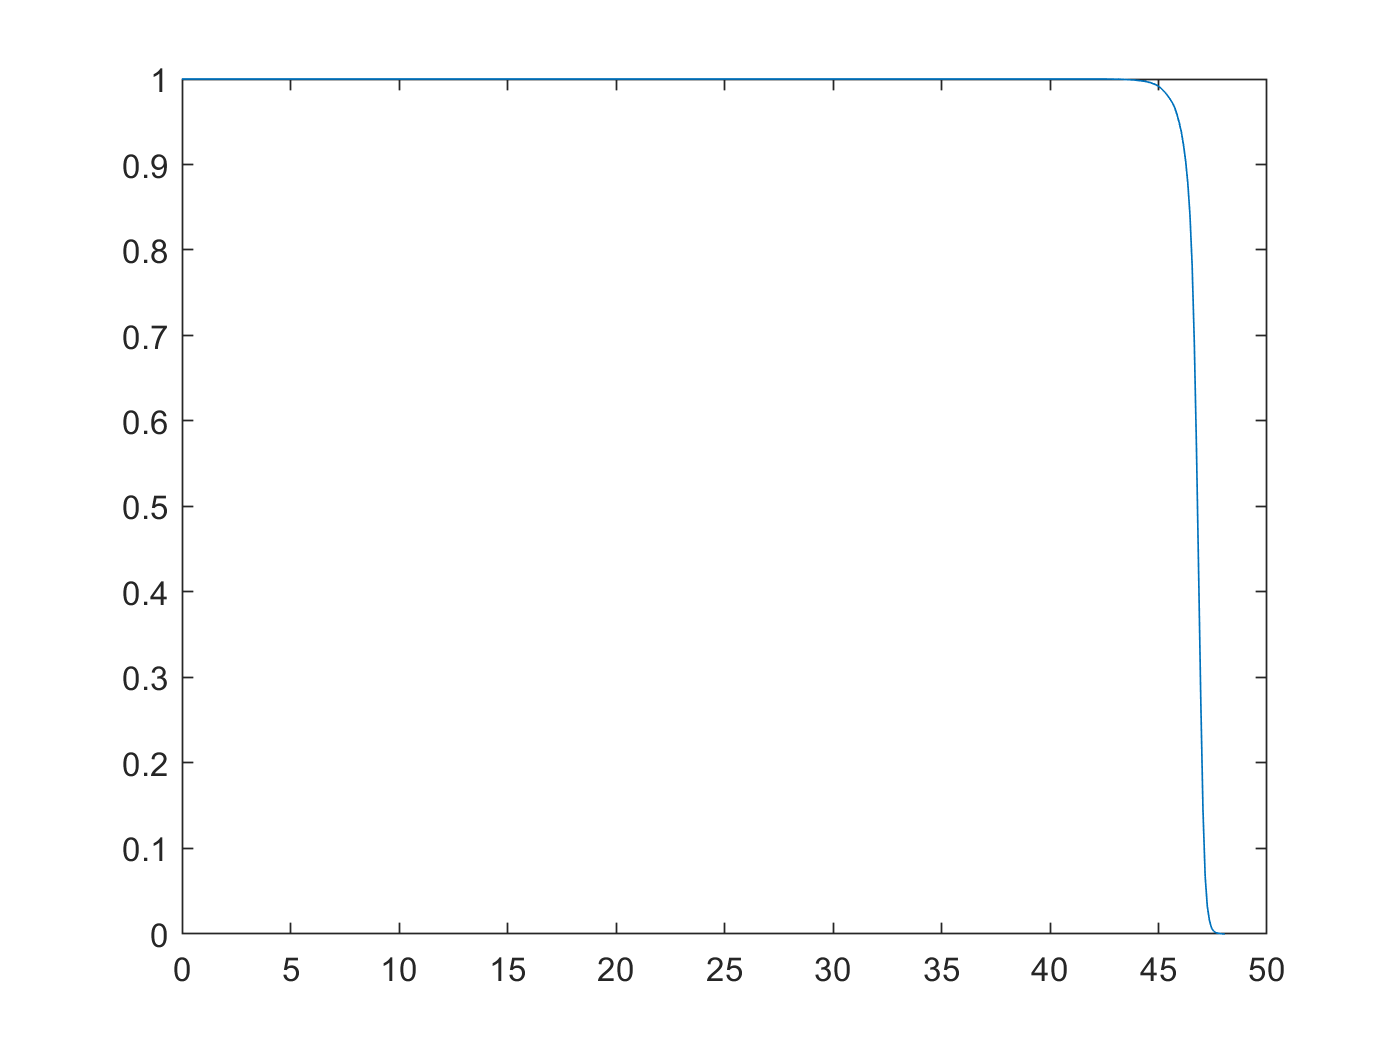

cumVolsV = cumsum(volsHistV);
cumVols2V  = cumVolsV(end) - cumVolsV;
% plot
figure,
plot([0, doseBinsV], [1, cumVols2V/cumVolsV(end)]);

size(volsHistV)

ans =      1   481


D95

Dx(planC, i_ptv, i_plan, 95)

ans = 45.9500

Dmax

maxDose(planC, i_ptv, i_plan, 'Percent')

ans = 48.0500

Dmin

minDose(planC, i_ptv, i_plan, 'Absolute')

ans = 42.6500

Dmean

meanDose(planC, i_ptv, i_plan, 'Percent')

ans = 46.7696

V95

volumeType (last argument)

1 = fractional

anything else = absolute volumes

sizeVolsHistV = size(volsHistV);
if not (sizeVolsHistV(1) == 1)
    volsHistV = volsHistV.';
end    
sizeDoseBinsV = size(doseBinsV);
if not (sizeDoseBinsV(1) == 1)
    doseBinsV = doseBinsV.';
end    
calc_Vx(doseBinsV, volsHistV, 46*0.95, 1)

ans = 0.9992

D95

Input volume assumed to be in percentage. Set volType=0 (last argument) for absolute values.

calc_Dx(doseBinsV, volsHistV, 95, 1)

ans = 45.9500

Mask

[strNum, structure] = getStructureFromName('PTV_Initial', planC);
mask3M = getUniformStr(strNum, planC);
[r,c,s, planC] = getUniformStr(strNum, planC);
stats = regionprops(mask3M);
stats.Centroid

ans =   264.8104  254.3204   70.8173


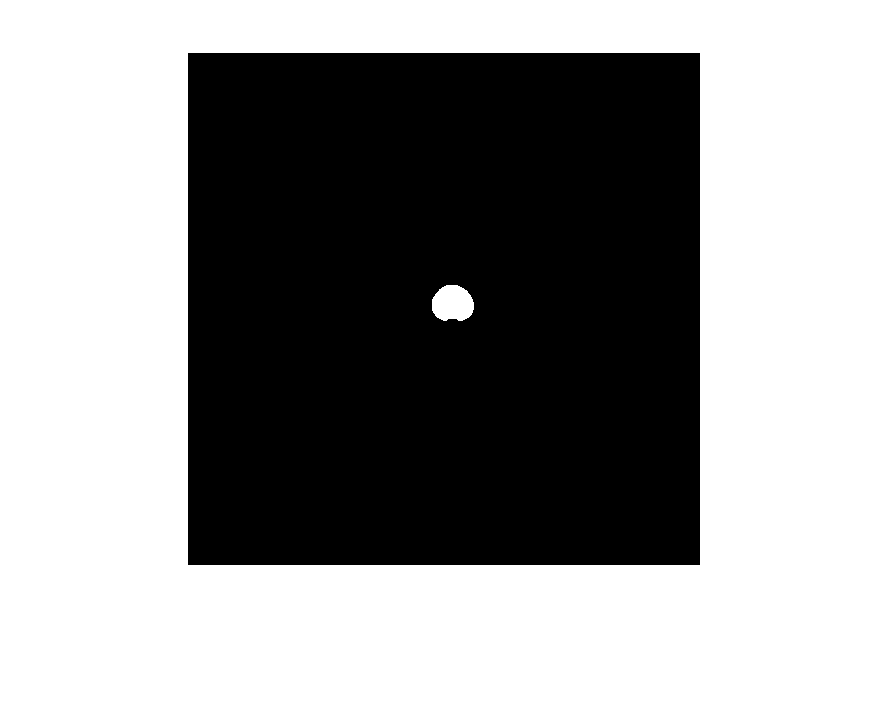

z = stats.Centroid(3);
z = cast(z,'int32');
imshow(mask3M(:,:,z))

Uniformized coordinate system Refer `getPBRayData.m`

[CTUniform3D, CTUniformInfoS] = getUniformizedCTScan(0, 1, planC);

%from getPBRayData.m
xOffset = CTUniformInfoS.xOffset;
yOffset = CTUniformInfoS.yOffset;
zFirst = CTUniformInfoS.firstZValue;
sliceThickness = CTUniformInfoS.sliceThickness;
numSlices = size(CTUniform3D,3);
%minBox an maxBox containt coordinates of the corners of the CT box as used
%by the ray intersection routine.
maxBoxS.z = (numSlices - 1) * sliceThickness + zFirst + sliceThickness/2;
minBoxS.z = zFirst - sliceThickness/2;
delta_xy = CTUniformInfoS.grid1Units;
imageWidth = CTUniformInfoS.size(2);
imageHeight = CTUniformInfoS.size(1);
minBoxS.x = - imageWidth/2 * delta_xy + xOffset;
maxBoxS.x =   imageWidth/2 * delta_xy + xOffset;
minBoxS.y = - imageHeight/2 * delta_xy + yOffset;
maxBoxS.y =   imageHeight/2 * delta_xy + yOffset;
% imageWidth = CTUniformInfoS.sizeOfDimension1
xs = 1:imageWidth;
ys = 1:imageHeight;
xs = xOffset + (xs - (imageWidth+1)*0.5)*delta_xy;
ys = yOffset - (ys - (imageHeight+1)*0.5)*delta_xy; % +y in the P-A direction

Dose matrix

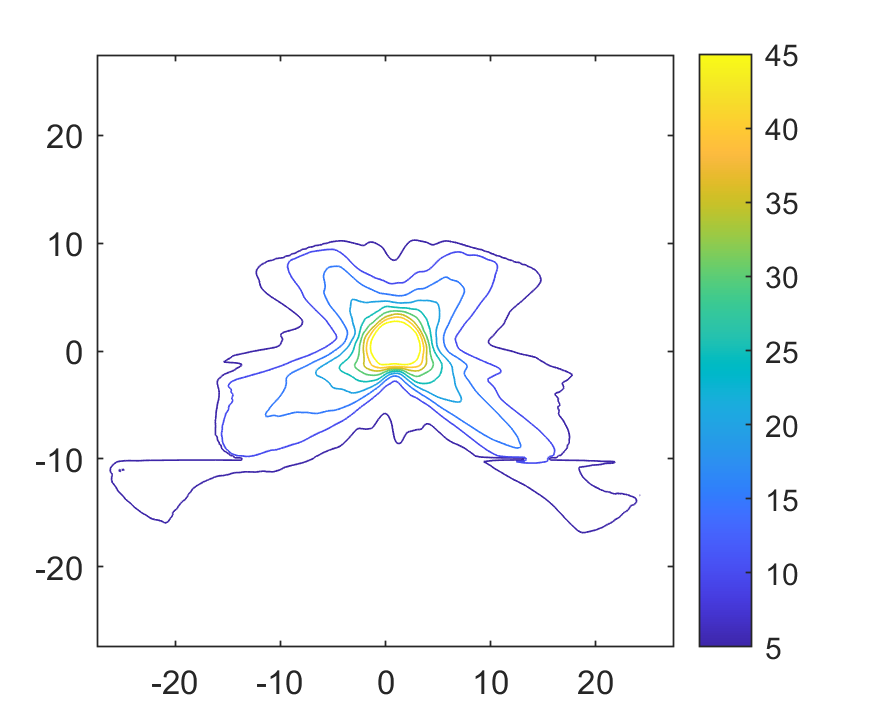

dose3M = getDoseOnCT(1, 1, 'uniform');
contour(xs, ys, dose3M(:,:,71));
colorbar;